# Exercise 5

### Problem 1

**a)**

clc
close all
clear all

% a) 
options = optimset('Display', 'off');
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = [];
lb = [0,0];
ub = [1,1];

fun = @(x)-(sin(4*pi*x(1))^4)*(sin(5*pi*x(2))^2)*(2-x(1))*(2-x(2));
% Iterates to give give different starting points
maxAltitude = 0;
for x1 = 0:0.1:1
    for x2 = 0:0.1:1
        x0 = [x1; x2];
        %x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub);
        [X,Z,exitflag] = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options);
        if exitflag == 1 && (-Z > maxAltitude)
            maxAltitude = -Z;
            Xopt_quadratic = X;    
        end
    end
end

Then the optimal for a rectangular constraint is:

Xopt_quadratic

Xopt_quadratic =     0.3740
    0.2988


**b)**

clc
close all
clear all

options = optimset('Display', 'off');
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = @circlecon;
lb = [];
ub = [];

fun = @(x)-(sin(4*pi*x(1))^4)*(sin(5*pi*x(2))^2)*(2-x(1))*(2-x(2));
% Iterates to give give different starting points
maxAltitude = 0;
for x1 = 0:0.1:1
    for x2 = 0:0.1:1
        x0 = [x1; x2];
        %x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub);
        [X,Z,exitflag] = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options);
        if exitflag == 1 && (-Z > maxAltitude)
            maxAltitude = -Z;
            Xopt_circular = X;    
        end
    end
end

Then the optimal for a circular constraint is:

Xopt_circular

Xopt_circular =     0.1242
    0.2988


#### Additional functions

@cirlecon

function [c,ceq] = circlecon(x)
c = (x(1)-0.5)^2 + (x(2)-0.5)^2 - (0.5)^2;
ceq = [];
end

### Problem 2

#### Functions

@odefun

function dydt = odefun(t, y, R, C)
    % Extract variables from the y vector
    xm = y(1);
    p = y(2);
    q = y(3);
    
    T = 0:pi/30:12*pi;
    fs = interp1(T,cos(T),t,'nearest');

    m = 0.3;
    I = m;

    % Define the system of ODEs
    xmdot = p/I;
    pdot  = R*(fs-p/I)+q/C;
    qdot  = fs-p/I;

    % Pack the derivatives into a column vector
    dydt = [xmdot; pdot; qdot];
end

@costfunction

function cost= costfunction(x)
R = x(1);
C = x(2);
[~,y] =ode45(@(t, y) odefun(t, y, R, C),[0 10*pi],[0 0 1]);
[t,y] =ode45(@(t, y) odefun(t, y, R, C),[10*pi:0.1:12*pi],y(end,:));
cost = sum(abs(y(:,1)-cos(t)));
end

Then the simultion goes as follows

clc 
close all
clear all

costFunc = @(x)costfunction(x);

A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = [];
lb = [0,0];
ub = [500,1];
x0 = (lb + ub)/2;

[Xopt,cost,exitflag] = fmincon(costFunc,x0,A,b,Aeq,beq,lb,ub);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



R_opt = Xopt(1);
C_opt = Xopt(2);

%Plot 
[t1,y1] =ode45(@(t, y) odefun(t, y, R_opt, C_opt),[0 10*pi],[0 0 1]);
[t2,y2] =ode45(@(t, y) odefun(t, y, R_opt, C_opt),[10*pi:0.1:12*pi],y1(end,:));


t12 = vertcat(t1,t2);
y12 = vertcat(y1(:,1),y2(:,1));

T = 0:0.1:12*pi;
cosinus = cos(T);

Where the optimal results for R and C are 

R_opt

R_opt = 249.7842

C_opt

C_opt = 0.8794

Plot with the respective variables

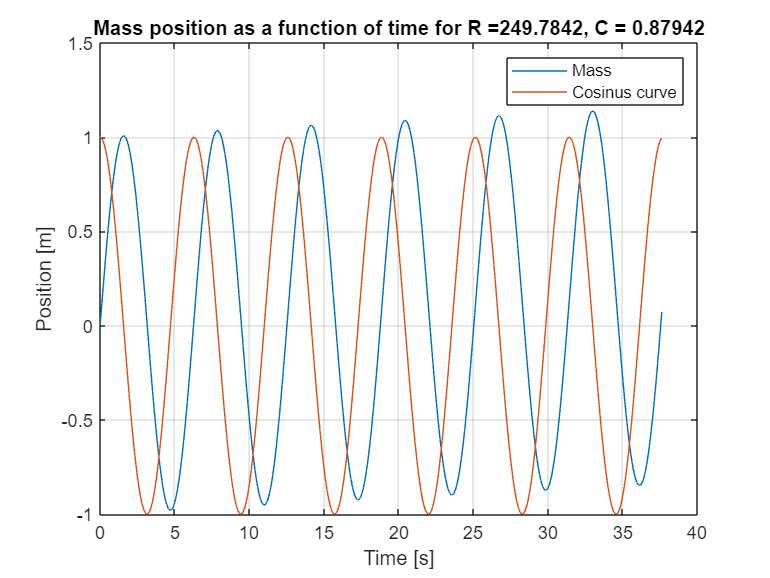

plot(t12,y12,T,cosinus)
grid on
legend('Mass','Cosinus curve')
title(['Mass position as a function of time for R =' ...
    num2str(R_opt),', C = ' num2str(C_opt)])
xlabel('Time [s]')
ylabel('Position [m]')